a) Read in an image and generate a list of image edges.

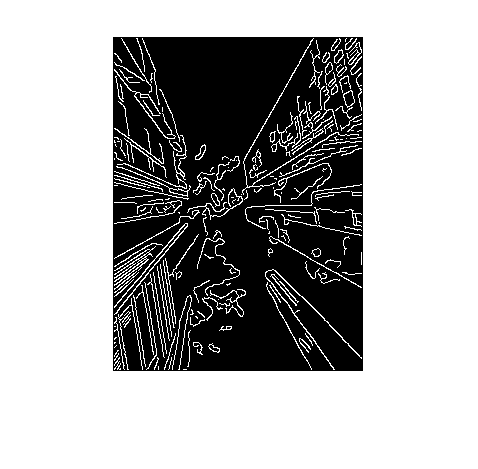

im = imread("./skyscrapers.jpg");
im = imresize(rgb2gray(im), 0.5);

Iedges = edge(im,'canny');
[~,grad_dir] = imgradient(im);
grad_dir = -grad_dir;
imshow(Iedges)


[row, col] = find(Iedges);
% Each edge is a 4-tuple: (x, y, cos theta, sin theta) 
edges = [col, row, zeros(length(row),1), zeros(length(row),1) ];
for k = 1:length(row)
     edges(k,3) = cos(grad_dir(row(k),col(k))/180.0*pi);
     edges(k,4) = sin(grad_dir(row(k),col(k))/180.0*pi);
end

Implement RANSAC

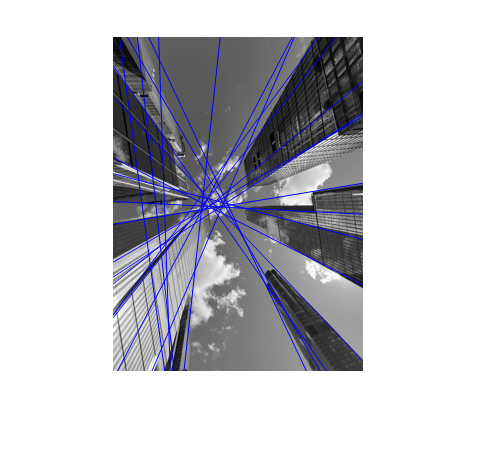

M = 500;
t = 3;
delta_theta = pi/20; 
Cmin = 100;
N = size(edges,1);

lineModel = [];
edge_mark = zeros(1,N);

for i = 1:M
    c = 0;
    cons = [];
    e = edges(randsample(N,1),:);
    for j = 1:N
        if edge_mark(1,j) == 0
            e1 = edges(j,:);
            d = abs(e(1,1)*e(1,3)+e(1,2)*e(1,4)-e1(1,1)*e(1,3)-e1(1,2)*e(1,4));
            o = abs(acos(e(1,3))-acos(e1(1,3)));
            if d <= t && o <= delta_theta
                c = c+1;
                cons(c,:) = [j,e1];
            end
        end
    end
    
    if c>Cmin
        lineModel(end+1,:) = mean(cons(:,2:5));
        for p = 1:c
            edge_mark(1,cons(p,1)) = 1;
        end
    end
    
end

[len_x, ~] = size(im);
for i = 1:size(lineModel,1)
    r = lineModel(i,1)*lineModel(i,3) + lineModel(i,2)*lineModel(i,4);
    start_y = r / lineModel(i,4);
    end_y = (r-len_x*lineModel(i,3)) / lineModel(i,4);
    im = insertShape(im,'Line',[0 start_y len_x end_y],'Color','blue');
end

imshow(im)

b)

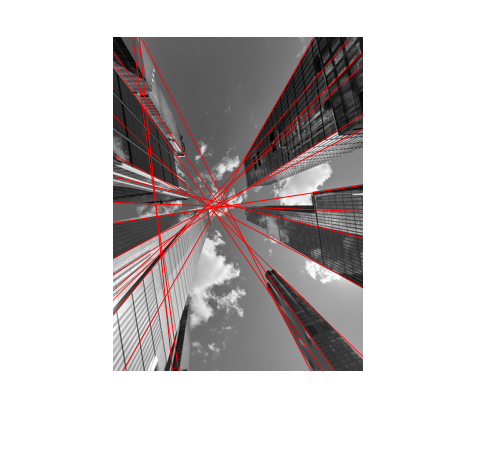

lineModel2 =[];
edge_mark2 = zeros(1,N);

for i = 1:M
    c = 0;
    cons = [];
    e = edges(randsample(N,1),:);
    for j = 1:N
        if edge_mark2(1,j) == 0
            e1 = edges(j,:);
            d = abs(e(1,1)*e(1,3)+e(1,2)*e(1,4)-e1(1,1)*e(1,3)-e1(1,2)*e(1,4));
            o = abs(acos(e(1,3))-acos(e1(1,3)));
            if d <= t && o <= delta_theta
                c = c+1;
                cons(c,:) = [j,e1];
            end
        end
    end
    
    if c>Cmin
        coefficients = polyfit(cons(:,2),cons(:,3),1);
        lineModel2(end+1,:) = coefficients;
        for p = 1:c
            edge_mark2(1,cons(p,1)) = 1;
        end
    end
    
end

im2 = imread("./skyscrapers.jpg");
im2 = imresize(rgb2gray(im2), 0.5);
[len_x, ~] = size(im2);
for i = 1:size(lineModel2,1)
    start_y = lineModel2(i,2);
    end_y = lineModel2(i,2) + lineModel2(i,1)*len_x;
    im2 = insertShape(im2,'Line',[0 start_y len_x end_y],'Color','red');
end
imshow(im2)